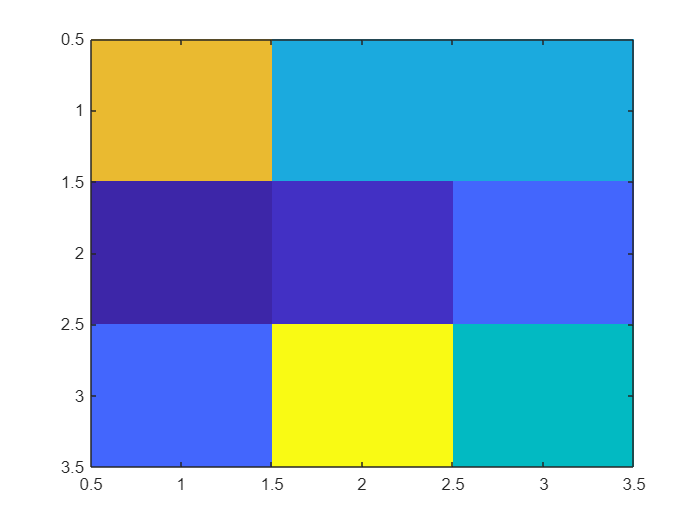

clear

X = [200 100 100; 0 10 50; 50 250 120];
Y = [100 220 230; 45 95 120; 205 100 0];

imagesc(X);

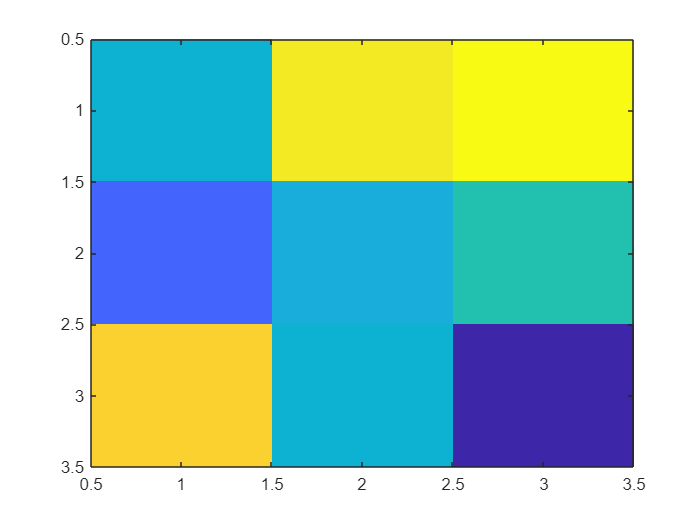

imagesc(Y);

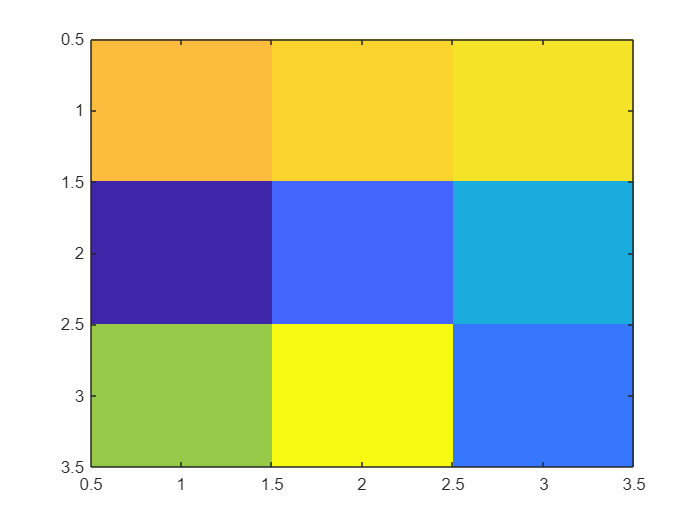


soma = X + Y;

imagesc(soma);

max = 0;
min = 255;

for i = 1:3
    for j = 1:3
        if(soma(i, j) > max)
            max = soma(i, j);
        end

        if(soma(i, j) < min)
            min = soma(i, j);
        end
    end
end
normalizacao = X;
for i = 1:3
    for j = 1:3 
        normalizacao(i, j) = (255/(max-min))*(soma(i, j)-min);
    end
end

imagesc(normalizacao);

truncado = X;

for i = 1:3
    for j = 1:3 
        truncado(i, j) = X(i, j) + Y(i, j)
        if(X(i, j) + Y(i, j) > 255)
            truncado(i, j) = 255
        end
        if(X(i, j) + Y(i, j) < 0)
            truncado(i, j) = 0
        end
    end
end

truncado =    300   100   100
     0    10    50
    50   250   120


truncado =    255   100   100
     0    10    50
    50   250   120


truncado =    255   320   100
     0    10    50
    50   250   120


truncado =    255   255   100
     0    10    50
    50   250   120


truncado =    255   255   330
     0    10    50
    50   250   120


truncado =    255   255   255
     0    10    50
    50   250   120


truncado =    255   255   255
    45    10    50
    50   250   120


truncado =    255   255   255
    45   105    50
    50   250   120


truncado =    255   255   255
    45   105   170
    50   250   120


truncado =    255   255   255
    45   105   170
   255   250   120


truncado =    255   255   255
    45   105   170
   255   350   120


truncado =    255   255   255
    45   105   170
   255   255   120


truncado =    255   255   255
    45   105   170
   255   255   120


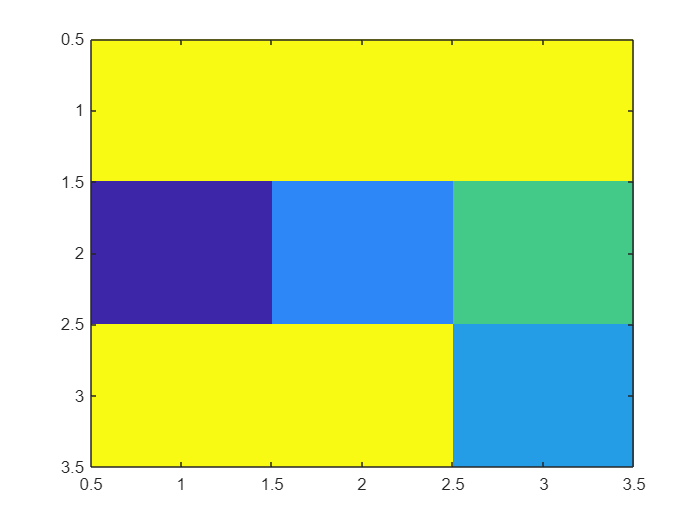


imagesc(truncado);